rng(0);
clear;

Consider the observed set of points of the form (x, y) ∈ R 2 in the file "points2D_Set1.mat". 

Assume each observation (x, y) is drawn independently from the joint probability density function P(X, Y ) of random variables X and Y . For this question, you cannot use the functions mean(), cov(), and pca() in Matlab.

load("points2D_Set1.mat");


 • (5 points) How can principal component analysis (PCA) be used to best approximate a linear rela�tionship between random variables X and Y . Describe the method clearly, using appropriate math�ematical descriptions for clarity. Your description should be clear enough to lead to a programmable implementation. 

To make a linear approximation, we would need a point on the line and the slope(direction) of the line. Expecting the data to be taken from a distribution whose scatter plot is linear, it would be a good idea for us to estimate the slope of the line by the direction of its maximum variation. Also, observe that for 

$Y = mX + c$, the point $(E[X], E[Y])
$ lies on this line. Hence, we shift our origin to this point and then find the direction of maximum variation to find the slope of the line.

From the slides, we know that the variance along a direction(unit vector) $v$ is given by $v^TCv$. We will now show that if $v$ corresponds to the eigenvector with the highest eigenvalue, then the variance will be maximum. 

Since $C$ is a symmetric matrix, from spectral theorem we know that $\exists Q \, Q^TCQ = D$ which means $C = QDQ^T$, where $D$ is a diagonal matrix and $Q$ is an orthogonal matrix. Hence, the variance can be rewritten as 

$v^TQDQ^Tv = (Q^Tv)D(Q^Tv)$. Since $D = [d_{ij}]$ is a diagonal matrix, we know that for that expression to have the maximum value, the value of $Q^Tv = e_j$ where $d_{jj} \geq d_{ii} \forall i$. This implies $v = Qe_j$ which is the same as the eigenvector corresponding to $d_{jj}$(the highest eigenvalue). If an eigenvalue has more than 2 orthogonal eigenvectors, then any one of those will give the highest variation along their repspective directions.  After we calculate $v$, we can calculate $m$

$m = \frac{v[1]}{v[0]}$.  Now we substitute this in the line equation and derive $c$ by using the fact that $(E[X], E[Y])$ is a point on that line.

• (5 points) Show a scatter plot of the points. Overlay on the scatter plot, the graph of a line showing the linear relationship between Y and X. 

xm = sum(x)/length(x);
ym = sum(y)/length(y);
p = [x';y'];
%sample cov
cov = p*p'/(length(x)-1) - (length(x))*[xm;ym]*[xm,ym]/(length(x)-1);

[Q,D] = eig(cov);
D = abs(diag(D)); 
[~, i_temp] = max(D)

i_temp = 2

w = zeros(length(D),1)

w =      0
     0


w(i_temp) = 1

w =      0
     1



v=Q*w 

v =     0.5247
    0.8513


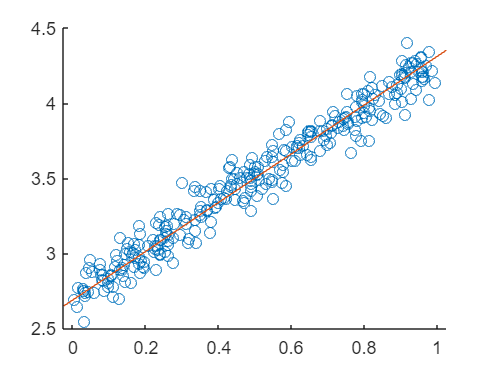

scatter(x,y); hold on;
plot(linspace(-1,1,10)*(v(1))+xm,linspace(-1,1,10)*(v(2))+ym)
hold off;

• (5 points) Repeat the same analysis for the set of points in "points2D_Set2.mat". Show a scatter plot of the points. Overlay on the scatter plot, the graph of a line showing the linear relationship between Y and X. Compared to the result on the other set of points, justify the quality of the approximation resulting in this question using logical arguments. 

load("points2D_Set2.mat");
xm = sum(x)/length(x);
ym = sum(y)/length(y);
p = [x';y'];
%sample cov
cov = p*p'/(length(x)-1) - (length(x))*[xm;ym]*[xm,ym]/(length(x)-1);

[Q,D] = eig(cov);
D = abs(diag(D)); 
[m_temp, i_temp] = max(D)

m_temp = 1.1048

i_temp = 2

w = zeros(length(D),1)

w =      0
     0


w(i_temp) = 1

w =      0
     1



v=Q*w 

v =    -0.9999
   -0.0162


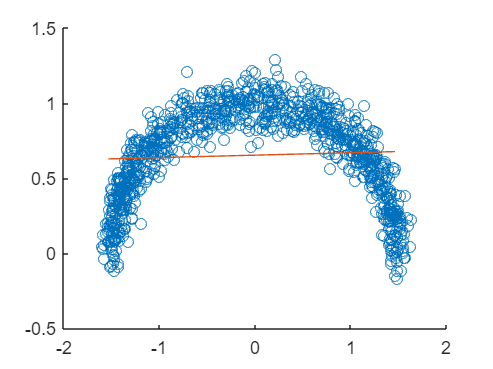

scatter(x,y); hold on;
plot(linspace(-1.5,1.5,10)*(v(1))+xm,linspace(-1.5,1.5,10)*(v(2))+ym)
hold off;